`首先收集实际数据或者用软件生成模拟数据，要求`25`组以上，每组至少`5`个以上样本；`

clear;
clc;

%书本例题原始数据
source_data=[15.0,15.8,15.2,15.1,15.9,
14.7,14.8,15.5,15.6,15.3,
15.0,15.6,15.7,15.8,14.5,
15.1,15.3,14.9,14.9,15.2,
15.9,15.0,15.3,15.6,15.1,
14.9,14.2,14.6,15.8,15.2,
15.2,15.0,14.9,14.8,15.1,
15.5,15.5,15.1,15.1,15.0,
15.3,14.7,14.5,15.5,15.0,
14.7,14.6,14.2,14.2,14.5];

num_groups = 25; % 定义组数为25
samples_per_group = 5; % 每组样本数为5
num_data_points = num_groups * samples_per_group; % 总数据点数为组数乘以每组样本数

% 复制数据源，使其长度大于或等于所需的数据点数
replicated_data = repmat(source_data, 1, ceil(num_data_points / length(source_data)));

% 从复制后的数据中取前num_data_points个数据，并添加随机扰动
perturbed_data = replicated_data(1:num_data_points) + 0.05 * randn(1, num_data_points);

x = 1:length(perturbed_data); % 原始数据的索引
xi = linspace(1, length(perturbed_data), num_data_points); % 插值后的索引
interpolated_data = interp1(x, perturbed_data, xi, 'spline'); % 使用样条插值进行数据插值

% 对插值后的数据进行四舍五入
interpolated_data = round(interpolated_data, 1);

% 将插值后的数据重塑为每组samples_per_group个样本，共num_groups组
expanded_data = reshape(interpolated_data, samples_per_group, num_groups)';

% 最终数据
data = expanded_data;

data=[   15.0000   14.6000   15.0000   15.1000   16.0000
   14.9000   15.2000   15.5000   15.2000   14.7000 
   15.7000   14.7000   15.6000   15.2000   15.0000
   14.2000   15.1000   15.5000   14.7000   14.6000
   15.2000   15.5000   15.7000   14.9000   15.3000
   14.7000   14.9000   15.1000   14.4000   14.3000
   15.1000   15.6000   15.8000   14.8000   15.6000
   15.9000   14.8000   15.1000   15.5000   14.3000
   16.0000   15.3000   14.6000   15.3000   15.1000
   15.2000   15.1000   15.1000   14.9000   14.6000
   15.0000   14.8000   14.9000   15.1000   15.9000
   14.9000   15.3000   15.5000   15.2000   14.7000
   15.8000   14.8000   15.6000   15.3000   14.9000
   14.1000   15.1000   15.4000   14.7000   14.6000
   15.2000   15.5000   15.7000   14.9000   15.3000
   14.6000   14.9000   15.0000   14.5000   14.3000
   15.2000   15.6000   15.8000   14.9000   15.6000
   15.8000   14.8000   15.1000   15.5000   14.2000
   15.9000   15.3000   14.5000   15.2000   15.1000
   15.2000   15.1000   15.0000   15.0000   14.5000
   15.0000   14.7000   15.0000   15.1000   16.0000
   14.9000   15.1000   15.6000   15.3000   14.6000
   15.7000   14.9000   15.6000   15.4000   14.9000
   14.2000   15.0000   15.5000   14.8000   14.7000
   15.2000   15.4000   15.6000   14.9000   15.2000
];
data

data =    15.0000   14.6000   15.0000   15.1000   16.0000
   14.9000   15.2000   15.5000   15.2000   14.7000
   15.7000   14.7000   15.6000   15.2000   15.0000
   14.2000   15.1000   15.5000   14.7000   14.6000
   15.2000   15.5000   15.7000   14.9000   15.3000
   14.7000   14.9000   15.1000   14.4000   14.3000
   15.1000   15.6000   15.8000   14.8000   15.6000
   15.9000   14.8000   15.1000   15.5000   14.3000
   16.0000   15.3000   14.6000   15.3000   15.1000
   15.2000   15.1000   15.1000   14.9000   14.6000


`数据描述性统计分析：均值，方差，极差，直方图等等指标；`

% 描述性统计分析
means = mean(data, 2); % 计算每组均值
variances = var(data, 0, 2); % 计算每组方差
ranges = range(data, 2); % 计算每组极差
stds = std(data, 0, 2);

disp('描述性统计结果:');

描述性统计结果:


disp(['组均值: ', num2str(means')]);

组均值: 15.14         15.1        15.24        14.82        15.32        14.68        15.38        15.12        15.26        14.98        15.14        15.12        15.28        14.78        15.32        14.66        15.42        15.08         15.2        14.96        15.16         15.1         15.3        14.84        15.26


disp(['组方差: ', num2str(variances')]);

组方差: 0.268       0.095       0.173       0.247       0.092       0.112       0.172       0.382       0.253       0.057       0.193       0.102       0.187       0.247       0.092       0.083       0.132       0.387        0.25       0.073       0.243       0.145       0.145       0.223       0.068


disp(['组标准差: ', num2str(stds')]);

组标准差: 0.51769     0.30822     0.41593     0.49699     0.30332     0.33466     0.41473     0.61806     0.50299     0.23875     0.43932     0.31937     0.43243     0.49699     0.30332      0.2881     0.36332     0.62209         0.5     0.27019     0.49295     0.38079     0.38079     0.47223     0.26077


disp(['组极差: ', num2str(ranges')]);

组极差: 1.4         0.8           1         1.3         0.8         0.8           1         1.6         1.4         0.6         1.1         0.8           1         1.3         0.8         0.7         0.9         1.6         1.4         0.7         1.3           1         0.8         1.3         0.7



overall_mean = mean(data(:)); % 总体均值
overall_variance = var(data(:)); % 总体方差
overall_range = range(data(:)); % 总体极差
overall_std = std(data(:));
%V = var(A) 返回 A 沿大小大于 1 的第一个数组维度计算的元素的方差。默认情况下，方差按 N-1 实现归一化，其中 N 是观测值数量。
disp('总体描述性统计结果:');

总体描述性统计结果:


disp(['总体均值: ', num2str(overall_mean)]);

总体均值: 15.1064


disp(['总体方差: ', num2str(overall_variance)]);

总体方差: 0.18657


disp(['总体标准差: ', num2str(overall_std)]);

总体标准差: 0.43194


disp(['总体极差: ', num2str(overall_range)]);

总体极差: 1.9



% 绘制直方图
figure;

% 绘制直方图并设置边界
h = histogram(data);
% 获取各组的边界
binEdges = h.BinEdges;

% 获取各组的宽度
binWidth = h.BinWidth;

% 获取各组的频数
binCounts = h.Values;
% 获取分组数
numBins = h.NumBins;

% 输出分组数
disp('Number of Bins:');

Number of Bins:


disp(numBins);

     8



% 输出各组的边界
disp('Bin Edges:');

Bin Edges:


disp(binEdges);

   13.8000   14.1000   14.4000   14.7000   15.0000   15.3000   15.6000   15.9000   16.2000




% 输出各组的宽度
disp('Bin Width:');

Bin Width:


disp(binWidth);

    0.3000




% 输出各组的频数
disp('Bin Counts:');

Bin Counts:


disp(binCounts);

     1     7    18    30    35    20    11     3



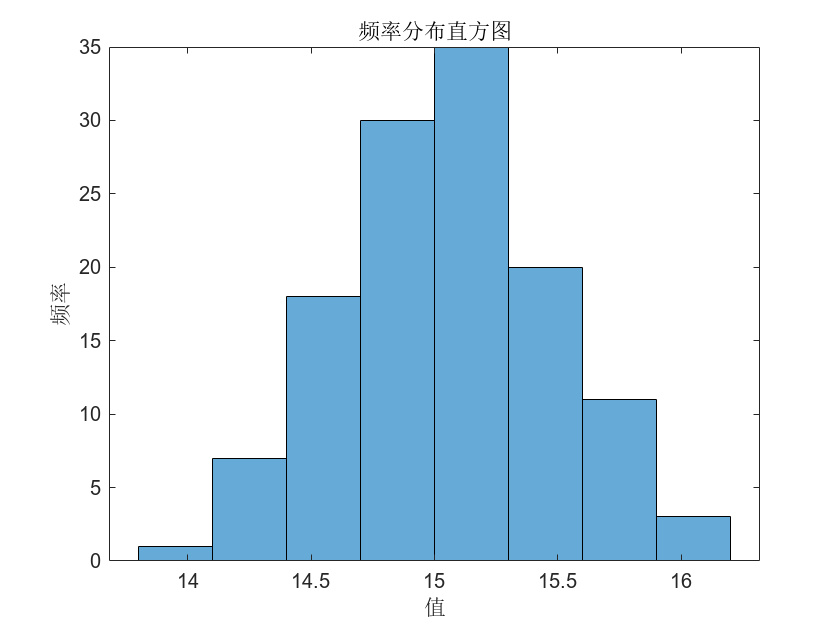

title('频率分布直方图');
xlabel('值');
ylabel('频率');

`数据正态性检验，以及总体均值检验；`

% 正态性检验 (使用Pearson-卡方检验)
% 方法一：直接调用函数
[result, p_chi2] = chi2gof(data(:));
disp(['正态性检验 p 值 (Pearson-卡方检验): ', num2str(p_chi2)]);

正态性检验 p 值 (Pearson-卡方检验): 0.37005


if result==0
    disp(['可认为数据来自正态分布的总体']);
else
    disp(['数据不来自正态分布总体']);
end

可认为数据来自正态分布的总体


% 关于chi2gof()函数：默认情况下验证是否为正态分布且显著性水平为5%
% h为检验结果，为0表示不拒绝原假设，即可认为数据来自正态分布的总体；为1则表示拒绝原假设，认为数据不来自正态分布的总体
% p_chi2返回的是正态性检验的p值，当p值大于显著性水平（默认5%）时不拒绝原假设

% 方法二：朴素思维
% 显著性水平delta=0.05
delta=0.05;
% 提出假设H0：F(x)=phi((x-miu)/sigma)
% 计算均值的MLE
mu_MLE = overall_mean;
% 计算方差的MLE
sigma2_MLE = overall_variance*(num_data_points-1)/num_data_points;  % 修正方差回调
sigma_MLE = sqrt(sigma2_MLE);
% 显示结果
disp(['均值的MLE: ', num2str(mu_MLE)]);

均值的MLE: 15.1064


disp(['方差的MLE: ', num2str(sigma2_MLE)]);

方差的MLE: 0.18508


% 分成8组，r=8
% 卡方分布维度dem=8-1-2=5
dimension=numBins-1-2;
% 临界值
criticalValue = chi2inv(1 - delta, dimension);
criticalValue

criticalValue = 11.0705

% 构造统计量
kafang=0;
p_hat(1)= normcdf(binEdges(2), mu_MLE, sigma_MLE);
for i=2:numBins-1
    p_hat(i)= normcdf(binEdges(i+1), mu_MLE, sigma_MLE)-normcdf(binEdges(i), mu_MLE, sigma_MLE);
end
p_hat(numBins)= 1-normcdf(binEdges(numBins), mu_MLE, sigma_MLE);
for i=1:numBins
    kafang=kafang+(binCounts(i)-num_data_points*p_hat(i))^2/(num_data_points*p_hat(i));
end
kafang

kafang = 2.6897

if kafang > criticalValue
    disp(['数据不来自正态分布总体']);
else
    disp(['可认为数据来自正态分布的总体']);
end

可认为数据来自正态分布的总体



% 总体均值检验 (使用t检验)
% 采用t检验的合理性是显然的，因为我们往往不知道正态分布总体的方差，即标准差sigma未知，此时需要构造服从t分布的统计量以进行t检验
% 方法一：直接调用函数
miu0=15.1;
[h, ttest_p_value] = ttest(data(:),miu0);
disp(['总体均值检验 p 值: ', num2str(ttest_p_value)]);

总体均值检验 p 值: 0.8687


if h==0
    disp(['可认为总体分布的均值为μ0=', num2str(miu0)]);
else
    disp(['总体分布的均值不为μ0=', num2str(miu0)]);
end

可认为总体分布的均值为μ0=15.1


%h = ttest(x) 使用单样本 t 检验返回原假设的检验决策，该原假设假定 x 中的数据来自均值等于零且方差未知的正态分布。备择假设是总体分布的均值不等于零。如果检验在 5% 的显著性水平上拒绝原假设，则结果 h 为 1，否则为 0。

%方法二：朴素思维
% 显著性水平delta=0.05
delta=0.05;
% 提出假设H0：miu=miu0
dimension=num_data_points-1;
s=sqrt(var(data(:)));
tCriticalValue = tinv(1 - delta/2, dimension)*s/sqrt(num_data_points);
d=abs(overall_mean-miu0);
d

d = 0.0064

tCriticalValue

tCriticalValue = 0.0765

if d>tCriticalValue
    disp(['总体分布的均值不为μ0=', num2str(miu0)]);
else
    disp(['可认为总体分布的均值为μ0=', num2str(miu0)]);
end

可认为总体分布的均值为μ0=15.1


`数据工序能力指数计算和评估；`

% 工序能力指数计算 (Cp 和 Cpk)
Tu=16.1;
Tl=14.1;
spec_limits = [Tl, Tu]; % 规格限
sigma = std(data(:)); % 总体标准差

cp = (spec_limits(2) - spec_limits(1)) / (6 * sigma); % 产品潜在工序能力指数Cp计算
cp

cp = 0.7717


Tu=16;
Tl=14;
spec_limits = [Tl, Tu]; % 规格限
T0=(spec_limits(2) + spec_limits(1)) / 2;
k=abs(overall_mean-T0)*2/(spec_limits(2) - spec_limits(1));
k

k = 0.1064

cpk=(spec_limits(2) - spec_limits(1)) *(1-k)/ (6 * sigma);%产品实际工序能力指数Cpk
cpk

cpk = 0.6896

% 若相对偏离度𝐾>1，则表示均值已偏离到规范范围以外，表明工艺加工结果很差，不适合量产；
% 当根据实际数据计算的Cpk小于0时，通常取Cpk=0，表明该工序完全没有能力。
% 当前国际上对现代电子工业界的要求，一般是实际生产工序能力指数不小于1.5。

disp(['Cp: ', num2str(cp)]);

Cp: 0.77171


disp(['Cpk: ', num2str(cpk)]);

Cpk: 0.6896



%单侧规范下的实际工序能力指数
cpu = (spec_limits(2) - mean(data(:))) / (3 * sigma); % Cpu计算
cpl = (mean(data(:)) - spec_limits(1)) / (3 * sigma); % Cpl计算
cpu

cpu = 0.6896

cpl

cpl = 0.8538


%某工序中连续采集了𝑘批工艺参数样本数据，每批次有𝑛个数据
%k=25,n=5
miu_hat=overall_mean;
sigma_hat=overall_variance;

figure;
plot(means, 'o-');
hold on;
CL= miu_hat;
UCL=miu_hat+3*sigma_hat;
LCL=miu_hat-3*sigma_hat

LCL = 14.5467

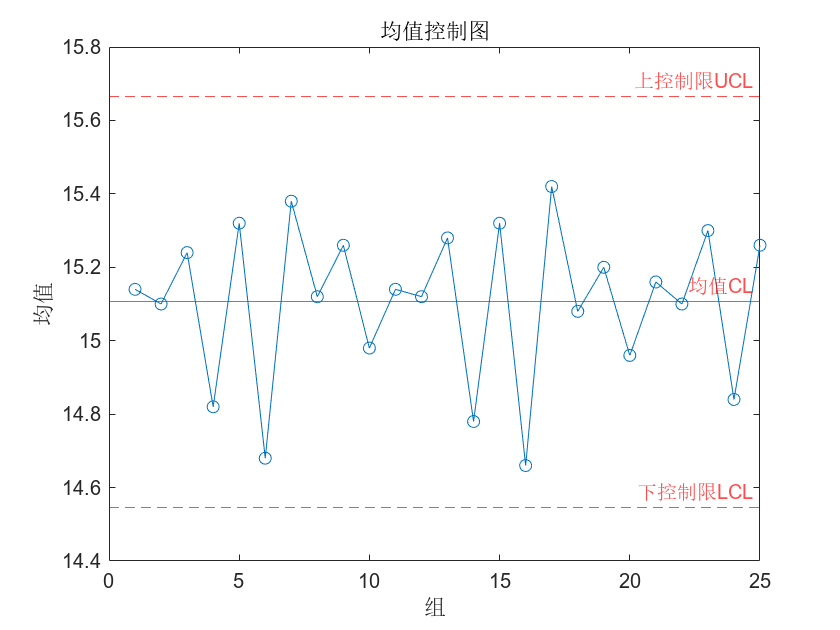

yline(CL, 'r-', '均值CL');
yline(UCL, 'r--', '上控制限UCL');
yline(LCL, 'r--', '下控制限LCL');
title('均值控制图');
xlabel('组');
ylabel('均值');
hold off;

`均值控制图和方差控制图描绘。`

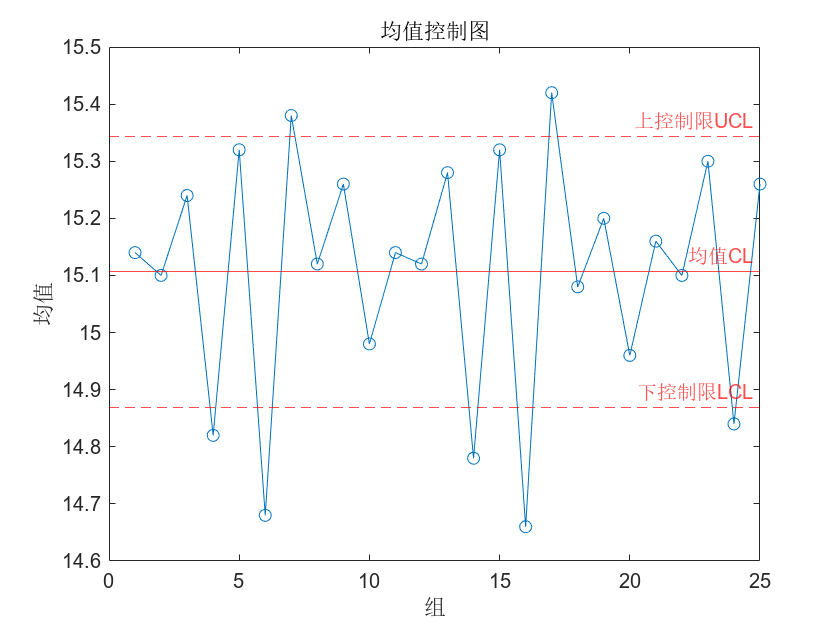

% 均值控制图
figure;
plot(means, 'o-');
hold on;
xi=mean(data, 2);
for i=1:num_groups
    sum=0;
    for j=1:samples_per_group
        sum=sum+((data(i,j)-xi(i))^2);   
    end
    si_hat(i)=sqrt(sum/(num_groups-1));
end
s_hat=mean(si_hat);
%每批次样本数据数n=5
%此时As=1.427,Bu=2.089,Bl=0
As=1.427;
Bu=2.089;
Bl=0;
CL= miu_hat;
UCL=miu_hat+s_hat*As;
LCL=miu_hat-s_hat*As;
yline(CL, 'r-', '均值CL');
yline(UCL, 'r--', '上控制限UCL');
yline(LCL, 'r--', '下控制限LCL');
title('均值控制图');
xlabel('组');
ylabel('均值');
hold off;

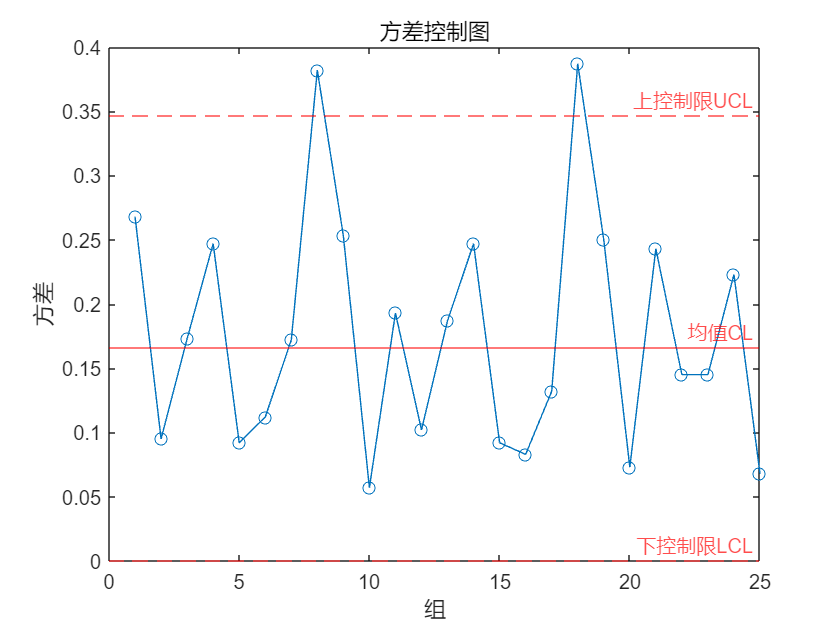


% 方差控制图
figure;
plot(variances, 'o-');
hold on;
UCL=(Bu*s_hat);
CL=(s_hat);
LCL=(Bl*s_hat);
yline(CL, 'r-', '均值CL');
yline(UCL, 'r--', '上控制限UCL');
yline(LCL, 'r--', '下控制限LCL');
title('方差控制图');
xlabel('组');
ylabel('方差');
hold off;

`作结论：工艺水平如何；生产过程是否处于统计受控状态。`

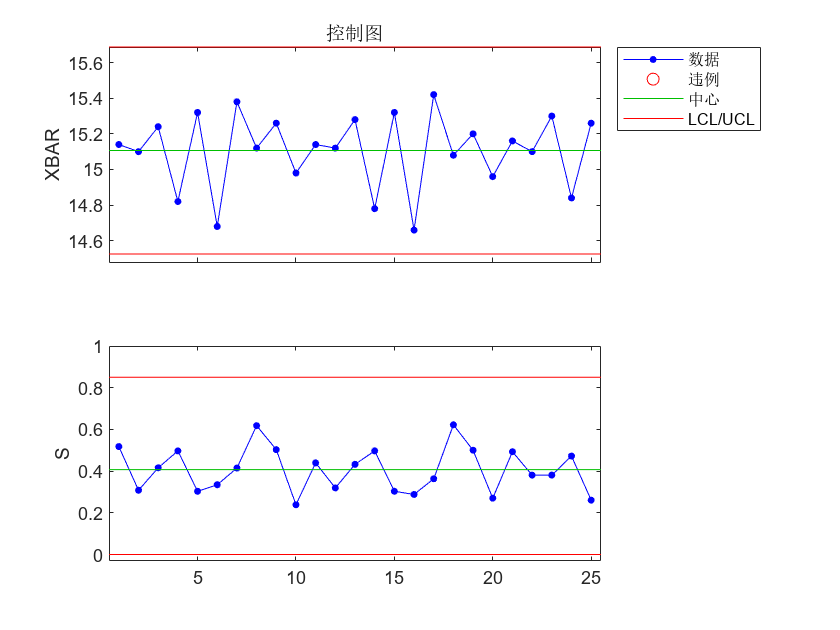

% 结论
% 规则1：控制图上有一个点(对应某个批次数据)位于控制限以外；
% 规则2：连续9个点落在中心线同一侧；
% 规则3：连续6个点递增或者递减；
% 规则4：连续14个点交替上下
% 规则5：连续3个点中有2个点落在中心线同侧的B区以外；
% 规则6：连续5个点中有4个点落在中心线同侧的C区以外；
% 规则7：连续15个点落在中心线两侧的C区；
% 规则8：连续8个点落在中心线两侧且无一点在C区以内。、

%调用controlchart函数
load parts
[st,plotdata] = controlchart(data,'charttype',{'xbar' 's'});

st.mu

ans = 15.1064

st.sigma

ans = 0.4329

plotdata.ooc%0为正常，1为异常

ans = 25×1 logical 数组
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0


ans = 25×1 logical 数组
   0
   0
   0
   0
   0
   0
   0
   0
   0
   0
